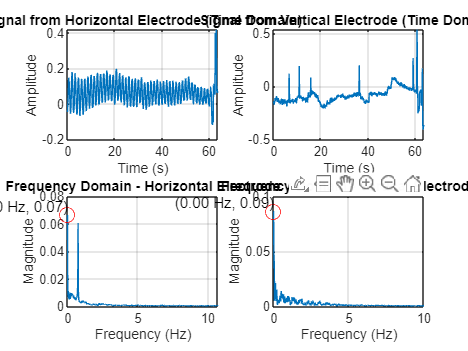

load('C:\Users\KAVIYA~1\AppData\Local\Temp\temp2623955714979689109tmp\kavi_eog.mat')

% Extract EOG signals from the 'data' variable
horizontal_signal = data(:, 1);
vertical_signal = data(:, 2);

% Constants
Fs = 1000; % Sampling frequency (Hz)

% Calculate time vector
t = (0:length(horizontal_signal)-1) / Fs; % Time vector (seconds)

% Plot signal from horizontal electrode in time domain
figure;
subplot(2,2,1);
plot(t, horizontal_signal);
title('Signal from Horizontal Electrode (Time Domain)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Plot signal from vertical electrode in time domain
subplot(2,2,2);
plot(t, vertical_signal);
title('Signal from Vertical Electrode (Time Domain)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Perform Fourier transform to obtain frequency domain representation for horizontal signal
Y_horizontal = fft(horizontal_signal);
L_horizontal = length(horizontal_signal);
P2_horizontal = abs(Y_horizontal/L_horizontal);
P1_horizontal = P2_horizontal(1:L_horizontal/2+1);
P1_horizontal(2:end-1) = 2*P1_horizontal(2:end-1);
f_horizontal = Fs*(0:(L_horizontal/2))/L_horizontal;

% Perform Fourier transform to obtain frequency domain representation for vertical signal
Y_vertical = fft(vertical_signal);
L_vertical = length(vertical_signal);
P2_vertical = abs(Y_vertical/L_vertical);
P1_vertical = P2_vertical(1:L_vertical/2+1);
P1_vertical(2:end-1) = 2*P1_vertical(2:end-1);
f_vertical = Fs*(0:(L_vertical/2))/L_vertical;

% Plot frequency domain representations
subplot(2,2,3);
plot(f_horizontal, P1_horizontal);xlim([0 10]);
title('Frequency Domain - Horizontal Electrode');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

% Find peak frequencies for horizontal and vertical eye movements
[max_amp_horizontal, max_index_horizontal] = max(P1_horizontal);
peak_frequency_horizontal = f_horizontal(max_index_horizontal);
peak_magnitude_horizontal = max_amp_horizontal;

[max_amp_vertical, max_index_vertical] = max(P1_vertical);
peak_frequency_vertical = f_vertical(max_index_vertical);
peak_magnitude_vertical = max_amp_vertical;

% Plot marker for peak frequency on horizontal plot
hold on;
plot(peak_frequency_horizontal, peak_magnitude_horizontal, 'ro', 'MarkerSize', 10);
text(peak_frequency_horizontal, peak_magnitude_horizontal, sprintf('(%.2f Hz, %.2f)', peak_frequency_horizontal, peak_magnitude_horizontal), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
hold off;

subplot(2,2,4);
plot(f_vertical, P1_vertical);xlim([0 10]);
title('Frequency Domain - Vertical Electrode');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

% Plot marker for peak frequency on vertical plot
hold on;
plot(peak_frequency_vertical, peak_magnitude_vertical, 'ro', 'MarkerSize', 10);
text(peak_frequency_vertical, peak_magnitude_vertical, sprintf('(%.2f Hz, %.2f)', peak_frequency_vertical, peak_magnitude_vertical), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
hold off;


% Calculate peak amplitudes of horizontal and vertical EOG signals
peak_amplitude_horizontal = max(horizontal_signal);
peak_amplitude_vertical = max(vertical_signal);
% Display results
fprintf('Frequency Analysis:\n');

Frequency Analysis:


fprintf('Peak Frequency of Horizontal Eye Movement (Hz): %f\n', peak_frequency_horizontal);

Peak Frequency of Horizontal Eye Movement (Hz): 0.000000


fprintf('Magnitude at Peak Frequency of Horizontal Eye Movement: %f\n', peak_magnitude_horizontal);

Magnitude at Peak Frequency of Horizontal Eye Movement: 0.066316


fprintf('Peak Frequency of Horizontal EOG (Hz): %f\n', peak_frequency_horizontal); % Assuming same as horizontal eye movement

Peak Frequency of Horizontal EOG (Hz): 0.000000


fprintf('Magnitude at Peak Frequency of Horizontal EOG: %f\n', peak_magnitude_horizontal);

Magnitude at Peak Frequency of Horizontal EOG: 0.066316


fprintf('Peak Frequency of Vertical Eye Movement (Hz): %f\n', peak_frequency_vertical);

Peak Frequency of Vertical Eye Movement (Hz): 0.000000


fprintf('Magnitude at Peak Frequency of Vertical Eye Movement: %f\n', peak_magnitude_vertical);

Magnitude at Peak Frequency of Vertical Eye Movement: 0.086288


fprintf('Peak Frequency of Vertical EOG (Hz): %f\n', peak_frequency_vertical); % Assuming same as vertical eye movement

Peak Frequency of Vertical EOG (Hz): 0.000000


fprintf('Magnitude at Peak Frequency of Vertical EOG: %f\n', peak_magnitude_vertical);

Magnitude at Peak Frequency of Vertical EOG: 0.086288


fprintf('\nAmplitude Analysis:\n');


Amplitude Analysis:


fprintf('Peak Amplitude of Horizontal EOG (mVolt): %f\n', peak_amplitude_horizontal);

Peak Amplitude of Horizontal EOG (mVolt): 0.417175


fprintf('Peak Amplitude of Vertical EOG (mVolt): %f\n', peak_amplitude_vertical);

Peak Amplitude of Vertical EOG (mVolt): 0.534058
